t_start = 0;
t_final = 1;
dt = 1/500;
n_step_time = (t_final-t_start)/dt;

x_start = 0;
x_final = 1;
dx = 1/31;
n_step_space = (x_final - x_start)/dx;

x = linspace(x_start, x_final, n_step_space);
t = linspace(t_start, t_final, n_step_time);

s = 0.5;
D = s*(dx^2)/dt;

T = zeros(n_step_space,n_step_time);
for j = 1:n_step_time
    T(1,j) = 100;
    T(n_step_space, j) = 100;
end

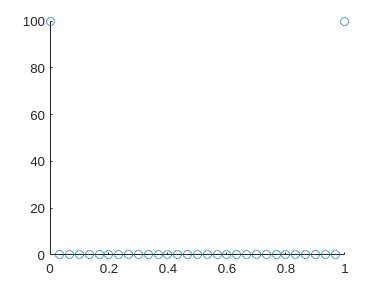

scatter(x, T(:,1))    

for j = 2:n_step_time
    for i = 2:n_step_space-1
        A = s*(T(i+1,j-1) - 2*T(i, j-1) + T(i-1,j-1));
        T(i,j) = T(i, j-1) + A;
    end
end


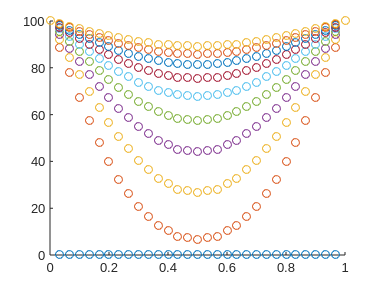

for j = 1:50:n_step_time
    scatter(x, T(:,j));
    hold on
end
hold off

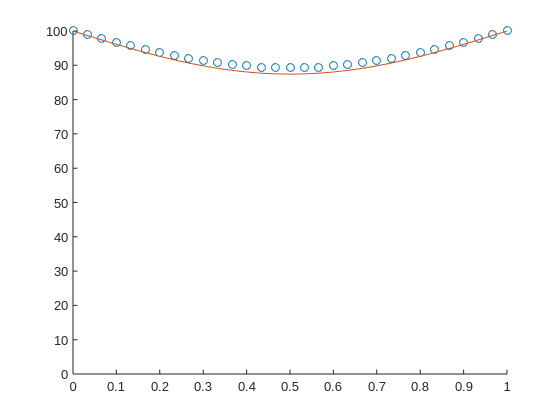

for j = 1:n_step_time
    scatter(x, T(:,j))
    pause (0.01)
end

T_sol = zeros(n_step_space, n_step_time);

NM = 10;
for j = 2:n_step_time
    time = t(j);
    for i = 1:n_step_space
        space = x(i);
        T_sol(i,j) = 100.0;
        for k = 1:NM
            SENO = sin((2*k-1)*pi*space);
            ESPO = exp(-D*((2*k-1)*pi)^2*time);
            COEFF = 400./(2*k-1)/pi;
            T_sol(i,j) = T_sol(i,j) - SENO*COEFF*ESPO;
        end
    
    end
end



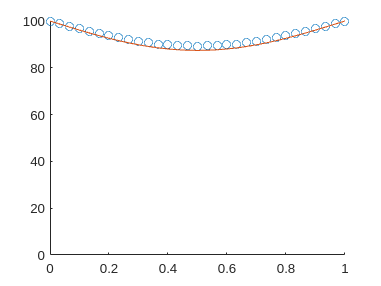


for j = 1:50:n_step_time
   
    scatter(x, T(:,j))
    hold on;
    plot(x, T_sol(:,j));

    xlim([0,1]);
    ylim([0,100]);

    hold off;

end